## Read in the oxy data

These people measured blood transmittance directly.  

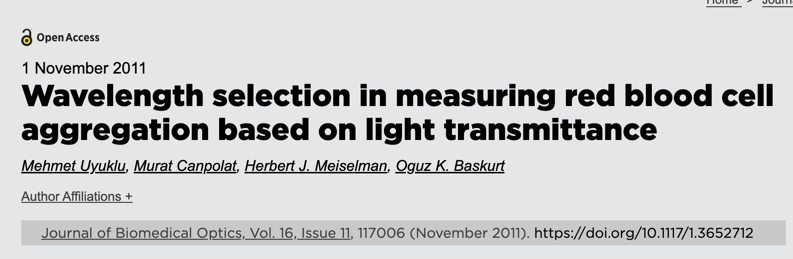

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

This plots shows the spectral transmittance through the blood at different optical densities.  We report log10(od) because the differences with respect to log10(od) are more equal.

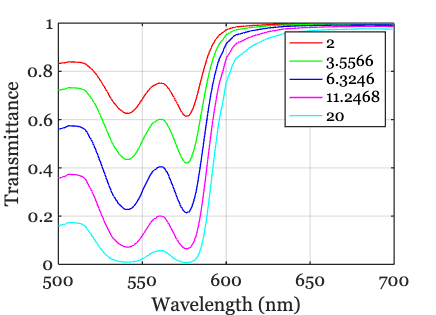

wave = 500:700;
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

ieFigure;
vals = logspace(log10(2),log10(20),5); 
for od = vals
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');
C = arrayfun(@num2str, vals, 'UniformOutput', false);
legend(C);


%{
% From the literature
bloodTransmittance = ieReadSpectra('bloodT1.mat',wave);
plot(wave,bloodTransmittance/50,'k-','LineWidth',3);
%}